**Translación en la Frecuencia**

%%Aplicando las propiedades 
clear all;
close all;
clc;

%Traslación en frecuencia
Fs=100;       %Frecuencia de muestreo
t=-1:1/Fs:2;  %Vector de tiempo
L=3000;       %Longitud de la señal 
A = 1;
s =((4/3)*(exp(1i*t*A))-2/3);%
Y=fft(s,L);   %Aplicando transformada rápida

plot(t,s);

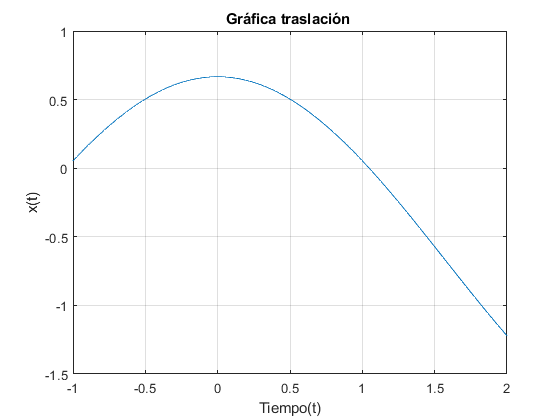

title('Gráfica traslación ')
xlabel('Tiempo(t)');
ylabel('x(t)');
grid on

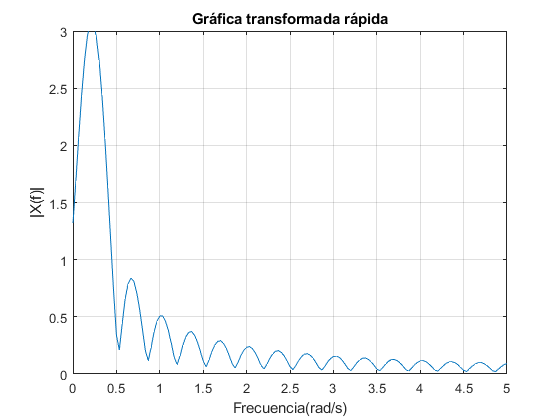

figure 

P=abs(Y/Fs);
f=linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica transformada rápida')
xlabel('Frecuencia(rad/s)')
ylabel('|X(f)|')
grid on

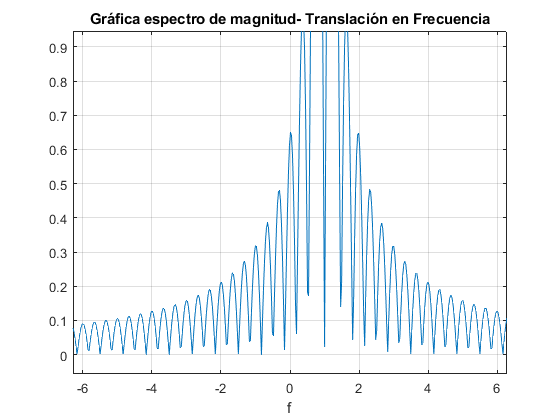



syms t f;       %Variables simbólicas
e=1;
x=exp(2*pi*1i*t*e)*((4/3)*t-2/3);  %
Tras_f=int(x*exp(-1i*2*pi*f*t),t,-1,2); %Transformada de Fourier teórica

ezplot(abs(Tras_f));
title('Gráfica espectro de magnitud- Translación en Frecuencia')
grid on

Espectro